K = 2.75;
Ve = 0;
Vx = 1.0;
esc = 1;
hz = 25.5;

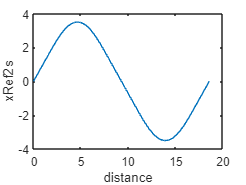

%%%%%%%%%%%%%%%%% race track %%%%%%%%%%%%%%%
R = 2;
D = 3;

x1 = 0;
y1 = 0;

th1 = 0:1:179;

for i = 1:180
    x2(i) = D/2 + R*sind(th1(i));
    y2(i) = R - R*cosd(th1(i));
end

for i = 1:180
    x3(i) = -D/2 - R*sind(th1(i));
    y3(i) = R + R*cosd(th1(i));

end
x4 = 0;
y4 = 0;

x = [x1 x2 x3 x4];
y = [y1 y2 y3 y4];

refPose =[x;y]'; 
xRef = refPose(:,1);
yRef = refPose(:,2);

% calculate distance vector
distancematrix = squareform(pdist(refPose));
distancesteps = zeros(length(refPose)-1,1);
for i = 2:length(refPose)
    distancesteps(i-1,1) = distancematrix(i,i-1);
end
totalDistance = sum(distancesteps); % Total distance travelled
distbp = cumsum([0; distancesteps]); % Distance for each waypoint
gradbp = linspace(0,totalDistance,1000); % Linearize distance

% linearize X and Y vectors based on distance
xRef2 = interp1(distbp,xRef,gradbp);
yRef2 = interp1(distbp,yRef,gradbp);
yRef2s = smooth(gradbp,yRef2); % smooth waypoints
xRef2s = smooth(gradbp,xRef2); % smooth waypoints
plot(gradbp,xRef2s)
xlabel('distance')
ylabel('xRef2s')

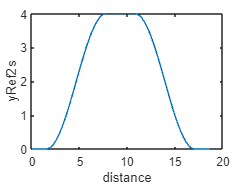


plot(gradbp,yRef2s)
xlabel('distance')
ylabel('yRef2s')

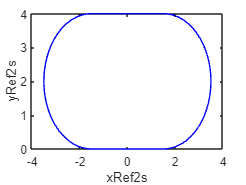


plot(xRef2s,yRef2,'b')
xlabel('xRef2s')
ylabel('yRef2s')

xRef = xRef2s;
yRef = yRef2s;


% % Reference point generating
% R = 1.2;
% D = 3;
% 
% x1 = 0;
% y1 = 0;
% 
% th1 = 0:1:89;
% 
% for i = 1:90
%     x2(i) = D/2 + R*sind(th1(i));
%     y2(i) = R - R*cosd(th1(i));
% end
% 
% for i = 1:90
%     x3(i) = D/2 +2*R - R*cosd(th1(i));
%     y3(i) = R + R*sind(th1(i));
% end
% 
% th2 = 0:1:179;
% 
% for i = 1:180
%     x4(i) = D/2 +2*R + R*sind(th2(i));
%     y4(i) = 3*R - R*cosd(th2(i));
% end
% 
% 
% x5 = D/2 ;
% y5 = 4*R;
% 
% for i = 1:90
%     x6(i) = -D/2 -R*sind(th1(i));
%     y6(i) = 3*R + R*cosd(th1(i));
% end
% 
% for i = 1:90
%     x7(i) = -D/2 -R*cosd(th1(i));
%     y7(i) = R - R*sind(th1(i));
% end
% 
% x8 = -0.1;
% 
% y8 = 0;
% x = [x1 x2 x3 x4 x5 x6 x7 x8];
% y = [y1 y2 y3 y4 y5 y6 y7 y8];
% 
% refPose =[x;y]'; 
% xRef = refPose(:,1);
% yRef = refPose(:,2);
% plot(xRef,yRef)
% xlabel('xRef')
% ylabel('yRef')
% 
% % calculate distance vector
% distancematrix = squareform(pdist(refPose));
% distancesteps = zeros(length(refPose)-1,1);
% for i = 2:length(refPose)
%     distancesteps(i-1,1) = distancematrix(i,i-1);
% end
% totalDistance = sum(distancesteps); % Total distance travelled
% distbp = cumsum([0; distancesteps]); % Distance for each waypoint
% gradbp = linspace(0,totalDistance,1000); % Linearize distance
% 
% % linearize X and Y vectors based on distance
% xRef2 = interp1(distbp,xRef,gradbp);
% yRef2 = interp1(distbp,yRef,gradbp);
% yRef2s = smooth(gradbp,yRef2); % smooth waypoints
% xRef2s = smooth(gradbp,xRef2); % smooth waypoints
% plot(gradbp,xRef2s)
% xlabel('distance')
% ylabel('xRef2s')
% 
% plot(gradbp,yRef2s)
% xlabel('distance')
% ylabel('yRef2s')
% 
% plot(xRef2s,yRef2,'b')
% xlabel('xRef2s')
% ylabel('yRef2s')
% xRef = xRef2s;
% yRef = yRef2s;


% % %%%%%%%%%%%%%%% Lane Change %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
% x1 = 0;
% y1 = 0;
% 
% x2 = 2;
% y2 = 0;
% 
% x3 = 5;
% y3 = 1;
% 
% x4 = 9;
% y4 = 1;
% 
% 
% x = [x1 x2 x3 x4];
% y = [y1 y2 y3 y4];
% 
% refPose =[x;y]'; 
% xRef = refPose(:,1);
% yRef = refPose(:,2);
% plot(xRef,yRef)
% xlabel('xRef')
% ylabel('yRef')
% 
% %%%%%calculate distance vector
% distancematrix = squareform(pdist(refPose));
% distancesteps = zeros(length(refPose)-1,1);
% for i = 2:length(refPose)
%     distancesteps(i-1,1) = distancematrix(i,i-1);
% end
% totalDistance = sum(distancesteps); % Total distance travelled
% distbp = cumsum([0; distancesteps]); % Distance for each waypoint
% gradbp = linspace(0,totalDistance,1000); % Linearize distance
% 
% %%%%%linearize X and Y vectors based on distance
% xRef2 = interp1(distbp,xRef,gradbp);
% yRef2 = interp1(distbp,yRef,gradbp);
% yRef2s = smooth(gradbp,yRef2); % smooth waypoints
% xRef2s = smooth(gradbp,xRef2); % smooth waypoints
% plot(gradbp,xRef2s)
% xlabel('distance')
% ylabel('xRef2s')
% 
% plot(gradbp,yRef2s)
% xlabel('distance')
% ylabel('yRef2s')
% 
% plot(xRef2s,yRef2,'b')
% xlabel('xRef2s')
% ylabel('yRef2s')
% xRef = xRef2s;
% yRef = yRef2s;


% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%% circle %%%%%%%%%%%%%%%%%%%%%%%%%%
% R = 1;                         
% th1 = 0:1:89;
% for i = 1:90
%     x1(i) = R*sind(th1(i));
%     y1(i) = R - R*cosd(th1(i));
% end
% for i = 1:90
%     x2(i) = R*cosd(th1(i));
%     y2(i) = R + R*sind(th1(i));
% end
% for i = 1:90
%     x3(i) = -R*sind(th1(i));
%     y3(i) = R + R*cosd(th1(i));
% end
% for i = 1:90
%     x4(i) = -R*cosd(th1(i));
%     y4(i) = R - R*sind(th1(i));
% end
% x = [x1 x2 x3 x4];%
% y = [y1 y2 y3 y4];%
% 
% refPose =[x;y]'; 
% xRef = refPose(:,1);
% yRef = refPose(:,2);
% 
% % calculate distance vector
% distancematrix = squareform(pdist(refPose));
% distancesteps = zeros(length(refPose)-1,1);
% for i = 2:length(refPose)
%     distancesteps(i-1,1) = distancematrix(i,i-1);
% end
% totalDistance = sum(distancesteps); % Total distance travelled
% distbp = cumsum([0; distancesteps]); % Distance for each waypoint
% gradbp = linspace(0,totalDistance,1000); % Linearize distance
% 
% % linearize X and Y vectors based on distance
% xRef2 = interp1(distbp,xRef,gradbp);
% yRef2 = interp1(distbp,yRef,gradbp);
% yRef2s = smooth(gradbp,yRef2); % smooth waypoints
% xRef2s = smooth(gradbp,xRef2); % smooth waypoints
% plot(gradbp,xRef2s)
% xlabel('distance')
% ylabel('xRef2s')
% 
% plot(gradbp,yRef2s)
% xlabel('distance')
% ylabel('yRef2s')
% 
% plot(xRef2s,yRef2,'b')
% xlabel('xRef2s')
% ylabel('yRef2s')
% xRef = xRef2s;
% yRef = yRef2s;


## Define vehicle parameters 

X_o = xRef(1); % initial vehicle position in x direction
Y_o = yRef(1); % initial vehicle position in y direction

## Calculate theta vector

**theta = orientation angle of the path at reference points **

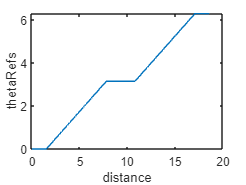

thetaRef = zeros(length(gradbp),1);
for i = 2:length(gradbp)
%     thetaRef(i,1) = atan2d((yRef2(i)-yRef2(i-1)),(xRef2(i)-xRef2(i-1)));
%     if (thetaRef(i,1) < 0)
%         thetaRef(i,1) = 180 + (180 + thetaRef(i,1));
%     else
%     end

    thetaRef(i,1) = atan2((yRef2(i)-yRef2(i-1)),(xRef2(i)-xRef2(i-1)));
     if (thetaRef(i,1) < 0)
         thetaRef(i,1) = pi + (pi + thetaRef(i,1));
     else
     end    

end
thetaRefs = smooth(gradbp,thetaRef); % smooth of theta
psi_o = thetaRefs(1)*(pi/180); % initial yaw angle

plot(gradbp,thetaRefs)
xlabel('distance')
ylabel('thetaRefs')

## Create direction vector

direction = ones(length(gradbp),1);


## Calculate curvature vector

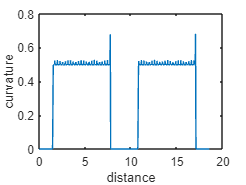

curvature = getCurvature(xRef2,yRef2);
plot(gradbp,curvature)
xlabel('distance')
ylabel('curvature')

path = [xRef2s';yRef2s';thetaRefs']';
xRef = xRef2s;
yRef = yRef2s;


## Curvature Function

function curvature = getCurvature(xRef,yRef)
% Calculate gradient by the gradient of the X and Y vectors
DX = gradient(xRef);
D2X = gradient(DX);
DY = gradient(yRef);
D2Y = gradient(DY);
curvature = (DX.*D2Y - DY.*D2X) ./(DX.^2+DY.^2).^(3/2);
end

*Copyright 2021 The MathWorks, Inc.*